%% OVERLAY Step-By-Step Tutorial
%% Author: Herbert Yao
%% Reviewer: NaN
% 
%% INTRODUCTION
% 
% This script is meant to provide a detailed and thorough explanation to 
% how to use OVERLAY and the thought process behind its development.
% Multiple functions from the toolbox will be featured. 
% 
% Please also refer to the journal paper, although it is written in a more
% high-level and conceptual way. This script will provide more insights on
% executional side.
% 
%% MATERIALS
% 
% Please make sure the following subjects are completed before proceeding
% with this tutorial:
% 
%   - Confirm the integrity of OVERLAY Toolbox
%   - Install COBRA Toolbox.
%   - MATLAB add-ons: Statistics and Machine Learning Toolbox
%                     Deep Learning Toolbox
%                     Bioinformatics Toolbox
%   - Gurobi 9.0 or above to be installed to use nonconvex QP. If you have
%     another solver installed (i.e., IBM CPLEX) then please skip that
%     section. The build-in solver of COBRA Toolbox will not do the trick
%     due to the size of the problem, so you need to install some other 
%     solvers to use OVERLAY.
% 
% Don't forget to take advantage of surfNet function to browse the model.

initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2023
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.39.3).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Original LP has 1 row, 2 columns, 1 non-zero
Objective value = 0
OPTIMAL SOLUTION FOUND BY LP PRESOLVER

 > [glpk] Primal optimality condition in solveCobraLP satisfied.Could not find installation of mosek, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle (ICME), Matt Zahr (ICME)
                     Aekaansh Verma (

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

			Support 	   LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    1 	    1 	    1 	    1 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek        	active        	    0 	    - 	    0 	    - 	    - 	    0
	matlab  

initializePROSO();

    PROSO Toolbox v1.0.1    


changeCobraSolver('gurobi','all',1);


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on the following mac OS versions: macOS 10.13+.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2021b.
 > changeCobraSolver: Solver for LP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on the following mac OS versions: macOS 10.13+.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2021b.
 > changeCobraSolver: Solver for MILP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on the following mac OS versions: macOS 10.13+.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2021b.
 > changeCobraSolver: Solver for QP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to M

clc;

%% PROCEDURE
% _1. Load and Examine M-model

% In this tutorial, we are using Pseudomonas aeruginosa metabolic
% reconstruction iSD1509 as an example.

if ~exist('model_ori','var')
    model_ori = readCbModel('iSD1509.xml');
    model_ori = setMediumMin(model_ori,'b');
    model_ori.lb(1214) = -20; % glucose
    model_ori.ub(1232) = 1000; % acetate
    model_ori.lb(1276) = -20; % succinate
    model_ori.ub(1276) = 1000;
    model_ori.lb(1285) = -1000; % oxygen
end

% It contains 1509 genes (+1 dummy), 1642 metabolites, and 2023 reactions.
% This model is set to growth on glucose and succinate (20mmol/h/gDW) under 
% aerobic conditions (1000mmol/h/gDW). 

FBAsol = optimizeCbModel(model_ori,'max');
fprintf('default M-model: growth rate: %.3f hr^-1\n',FBAsol.f);

default M-model: growth rate: 2.919 hr^-1


fprintf('                 glucose consumption rate: %.3f mmol/gDW/h\n',FBAsol.v(1214));

                 glucose consumption rate: -20.000 mmol/gDW/h


fprintf('                 succinate consumption rate: %.3f mmol/gDW/h\n',FBAsol.v(1276));

                 succinate consumption rate: -20.000 mmol/gDW/h


fprintf('                 oxygen consumption rate: %.3f mmol/gDW/h\n',FBAsol.v(1285));

                 oxygen consumption rate: -59.209 mmol/gDW/h



% Note that M-model has a tendency to exhaust all materials given. This is
% often undesirable and unrealistic simulation. 

% _2. Construct PC-model

% Constructing PC-model with OVERLAY toolbox is simple: it only requires an
% M-model and an appropriate protein FASTA file (.faa). The FASTA file is
% required solely for calculating the molecular mass of each protein. 

if ~exist('model_pc_ori','var')
    [model_pc_ori,fullProtein,fullCplx,C_matrix,K_matrix,fullProteinMM]...
        = pcModel(model_ori,'Pseudomonas_aeruginosa_UCBPP-PA14_109.faa',150);
end

% You should see there's a line saying "Not found gene: PA_s0001". This is
% fine because PA_s0001 is a dummy gene in the reconstruction and does not
% point to any real genes in the P. aeruginosa genome. PA_s0001 will
% therefore be assigned an average molar weight. 
% If there are too many genes in the M-model that are not found in FASTA
% file, you may need to check if your FASTA heading and model.genes are
% using the same gene identifier. 

% 150 stands for protein weight constraint is set to 150 mg/gDW. 120-200 is
% usually a reasonable for this param. Note that although the total protein
% contents of a cell is usually around 50%, M-model usually models about
% 1/3 to 1/4 of the total protein. This protein weight constraint can be 
% easily changed later i.e., 

model_pc_ori.b(find(strcmp(model_pc_ori.mets,'proteinWC'))) = 120;

% Regarding outputs from PC-model constructor:
% 
%   model_pc_ori: PC-model is usually a lot larger than M-model and
%                 contains many classes of new metabolites and reactions. 
% 
%   fullProtein: a list of protein metabolites added to PC-model, it should
%                have the same length as model_ori.genes
% 
%   fullCplx: a list of complex metabolites added to PC-model. This list is
%             parsed from model_ori.grRules so it can be larger or smaller.
%             If model_ori.grRules contains very complex combinations,
%             fullCplx tends to growth exponentially, which is undesirable.
% 
%   C_matrix: a matrix with each row representing a protein in fullProtein
%             and each column representing a complex in fullCplx. This
%             matrix contains information of protein complex compositions.
%             For example, complex 15 has two subunits, PA14_10990 (protein
%             16) and PA14_11000 (protein 17), so column 15 in C_matrix is 
%             sparse except row 16 and 17 being 1. 
% 
%   K_matrix: a matrix with each row representing a reaction in
%             model_ori.rxns and each column representing a complex in
%             fullCplx. This matrix contains information of whether a
%             complex can catalyze a reaction. For example, complex 15 can
%             catalyze reaction 3HPAOX (rxn 33) and HPA3MO (rxn 670), so 
%             column 15 in K_matrix is sparse except row 33 and 670. Note
%             that all non-zero entries are now 234000, which is the
%             default enzymatic rate constant of 65 s^-1 or 234000 hr^-1.
% 
%   fullProteinMM: vector of protein molar weight. This is calculated from
%                  the protein FASTA file. Heavier proteins contribute more
%                  toward proteinWC, please check EX_protein reactions in
%                  model_pc_ori.rxns to get a deeper understanding
% 
% All information above is already implemented into model_pc_ori, but they
% can be output explicitly to make them easier to access and understand. 


% _3. Refine PC-model

% PC-model can be further refined through semi-manual procedures. 

% Step 1 is manually curating protein complex stoichiometry. Currently all
% non-zero entries in C_matrix are filled with 1. If through some data
% source (i.e., metacyc) you can have access to measured protein complex
% stoich, it is better to update C_matrix with better information. 
% 
% For example, if I find the protein complex for 3HPAOX and HPA3MO (complex
% 15) contains one protein molecule from PA14_10990 but two molecules of 
% PA14_11000 (protein 17), I can update this information directly to 
% C_matrix as follows:

if ~exist('model_pc','var')
    C_matrix(17,15) = 2;

% And you should do this for all information you can find before proceeding

% Step 2 is updating enzymatic rate constant (K_eff). Now they are at their
% default values. Often times we can not find enough experimental
% measurements of enzyme kinetics. However, there is a method that allows
% us to systematically estimate them coarsely using their molar weight.
% Details of this is in the paper so please read it through if you have
% further questions. Other Keff estimation methods may also work here. 

    K_matrix = estimateKeffFromMW(C_matrix,K_matrix,fullProteinMM);

% Step 3 is implementing the new C_matrix and K_matrix into PC-model

    model_pc = adjustStoichAndKeff(model_pc_ori,C_matrix,K_matrix);
end

% It will take some time to update all information to the PC-model, you
% should be able to see in the console it is going through proteins and 
% complex one at a time.
% The PC-model is now considered complete.

% PC-model is quite difference from M-model in its behaviors. 

model_pc.lb(1276) = -20; % make sure succ is available to cell 
FBAsol = optimizeCbModel(model_pc,'max');

fprintf('PC-model: growth rate: %.3f hr^-1\n',FBAsol.f);

PC-model: growth rate: 0.707 hr^-1


fprintf('          glucose consumption rate: %.3f mmol/gDW/h\n',FBAsol.v(1214));

          glucose consumption rate: -20.000 mmol/gDW/h


fprintf('          succinate consumption rate: %.3f mmol/gDW/h\n',FBAsol.v(1276));

          succinate consumption rate: -7.783 mmol/gDW/h


fprintf('          oxygen consumption rate: %.3f mmol/gDW/h\n',FBAsol.v(1285));

          oxygen consumption rate: -18.486 mmol/gDW/h


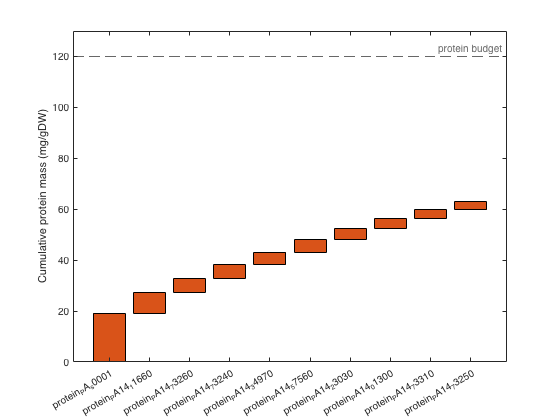


% Note that the cell is no longer exhausting all resources given to it. In
% this simulation, it appears P. aeruginosa prefers glucose over succinate,
% which is impossible to observe from M-model.

% _4. Extra understanding of PC-FBA and PC-model

% Apart from common traits of FBA, using FBA on PC-model (or PC-FBA) can
% also unveil the optimal proteome. Protein abundance vector can be easily
% extracted from FBAsol.v, protein dilution reactions (all reaction with
% its name starts with "EX_protein_")

% For example, let's find and plot the 10 most abundant protein by mass

proteinExIdx = find(startsWith(model_pc.rxns,'EX_protein_'));
proteinIdx = find(startsWith(model_pc.mets,'protein_'));

M_protein = abs(FBAsol.v(proteinExIdx)) .* fullProteinMM * 1e-6;
[v,i] = maxk(M_protein,10);

for j = 1:10
    if j == 1
        b(j,1) = 0;
    else
        b(j,1) = sum(v(1:j-1));
    end
end

X = categorical(model_pc.mets(proteinIdx(i)));
X = reordercats(X,model_pc.mets(proteinIdx(i)));

figure;
h = bar(X,[b,v],'stacked');
h(1).Visible = 'off';
yline(sum(M_protein),'--','protein budget');
set(gca,'YLim',[0,sum(M_protein)+10]);
set(gca,'DefaultAxesTickLabelInterpreter','none');
ylabel('Cumulative protein mass (mg/gDW)');

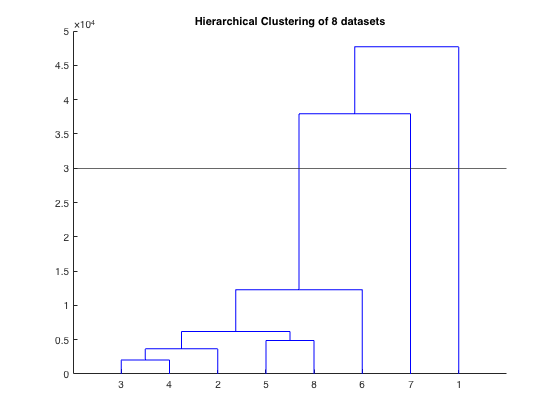


clear X h b i j v;

% Here you can make several observations (please make sure you are able to
% see these yourself:
% 
%   1. The most abundant protein is the dummy. This makes sense as the
%      dummy protein actually represents multiple proteins. 
%   2. The second most abundant protein is a water transporter
%      (PA14_11660). You can explore within the model visually by:
%      >> surfNet(model_pc,'protein_PA14_11660')
%   3. The sum of all protein mass is exactly at 120mg/gDW, which is the
%      same as the protein budget we set previously. This should almost
%      always be the case (but can occasionally be otherwise). Note that
%      all protein concentrations (so does cplx) in FBAsol are in nmol/gDW
%      so we are not working with tiny numbers. fullProteinMM are
%      calculated in mg/mmol, so M_protein is multiplied by a factor of 
%      1e-6 for unit conversions. 

% shut down succ so the cell growth solely on glc for later analysis
model_pc.lb(1276) = 0;  

% _5. Prepare RNA-seq data

% The key contribution of OVERLAY is to unveil underlying metabolism for a
% RNA-seq measurement. Let's take a processed RNA-seq dataset as an
% example: E-GEOD-55197
% 
% source study: Dötsch, A., Schniederjans, M., Khaledi, A., Hornischer, 
%               K., Schulz, S., Bielecka A., ... & Häussler, S. (2015). 
%               The Pseudomonas aeruginosa transcriptional landscape is 
%               shaped by environmental heterogeneity and genetic 
%               variation. MBio, 6(4), e00749-15.

% Load data into a table dt
% 
% This is only a showcase, so we are only loading 8 set of RNA-seq data of
% 8 conditions. I'm not showcasing RNA-seq processing algorithms, thus this 
% part is omitted. Please apply appropriate data preprocessing algorithms 
% before using OVERLAY for the maximum success. 

addpath('E-GEOD-55197/');

fileNames = {'GSM1331366_exp.1.txt','GSM1331354_anox.1.txt',...
    'GSM1331360_bf24.1.txt','GSM1331362_bf48.1.txt',...
    'GSM1331374_heat42.1.txt','GSM1331376_heat50.1.txt',...
    'GSM1331392_stat.1.txt','GSM1331394_trans.1.txt'};

expNames = {'exponential','anoxic','biofilm24h','biofilm48h',...
    'heat42C','heat50C','stationary','transition'};

for i = 1:length(fileNames)
    if i == 1
        dt = renamevars(readtable(fileNames{i},'ReadRowNames',true),'Var1',expNames{i});
    else
        dt = [dt,renamevars(readtable(fileNames{i},'ReadRowNames',true),'Var1',expNames{i})];
    end
end

% This expression data need to be truncated and put into the order of
% fullProtein, essentially a 1510*8 double.
% 
% We also need a cell (waiver) that contains all modelled proteins that 
% don't have RNA-seq measurement in the data, which are then waivered from
% OVERLAY. In this case, the only waiver is the dummy protein. 
% 
% A long waiver list is always undesirable.

data = zeros(length(fullProtein),length(expNames));
waiver = {};

for i = 1:length(fullProtein)
    idx = find(contains(dt.Row,fullProtein{i}));

    if ~isempty(idx)
        if length(idx) ~= 1
            warning('Protein %s: duplicating data entry\n',fullProtein{i});
        end
        data(i,:) = dt{idx,:};
    else
        waiver{end+1,1} = ['protein_',fullProtein{i}];
    end
end

clear i;

% As it is commonly the case, different experimental conditions results in
% vastly different absolute abundance. Recall that we made an assumption on
% modelled protein abundance (fixed at 120mg/gDW). Now we have two options:
% 
%   1. Scale each column in data so they add to the same absolute
%      abundance. This is the default option by OVERLAY, and will result in
%      every context-specific model will have the same protein budget. If
%      this is what you want, the data preparation has completed and
%      OVERLAY will automatically do the scaling for you. 
% 
%   2. Re-estimate a context-specific protein budget using expression data.
%      This can also be done pretty easily: 
%      (a) Compose a completeProteinMM for all rows in dt (6014*1) by
%          finding respective ids in FASTA and calculate their molar weight
%          using the function calcProteinMM
%      (b) Make an assumption of total protein mass contents in the cell
%          (say 600mg/gDW)
%      (c) for i-th experiment condition, protein budget is:
%          600 * data(:,i)'*fullProteinMM / dt{:,i}'*completeProteinMM
% 
% For the sake of simplicity, we will stick with option 1 in this tutorial.

% _6. Non-convex QP for keff tuning

% You can in fact completely skip this section. Non-convex QP is NOT a must
% for convex QP or subsequent analyses, although I believe it's better to 
% have it. If you don't have access to Gurobi, please skip to Convex QP. 
% 
% Non-convex QP tunes enzymatic rate constants before convex QP. 
% 
% It can be understood as enzymatic rate constant estimation on a system
% level, although I am not inclined to market it this way. This is because 
% the system of equations is very under-determined + expression data is
% noisy by its nature. I am more inclined to understand it as using the
% uncertainty in enzymatic rate constants to the advantage of this
% algorithm to fit expression data better. 

% Non-convex QP is a very large QP with non-convex constraints. Currently
% Gurobi 9.0+ is capable of solving it despite being very time and memory
% consuming. I'm using MacBook Pro with M1 chip and 16G RAM, and it seems I
% can give non-convex QP algorithm up to 4 sets of data before running out
% of RAM. If you have access to better device, you may afford to input a
% few more sets of data.
% 
% Since we have 8 sets of data to begin with, we can quickly do a
% hierarchical clustering to make it less than 4 for non-convex QP.

figure;
dendrogram(linkage(pdist(data')));
title('Hierarchical Clustering of 8 datasets');
yline(3e4);

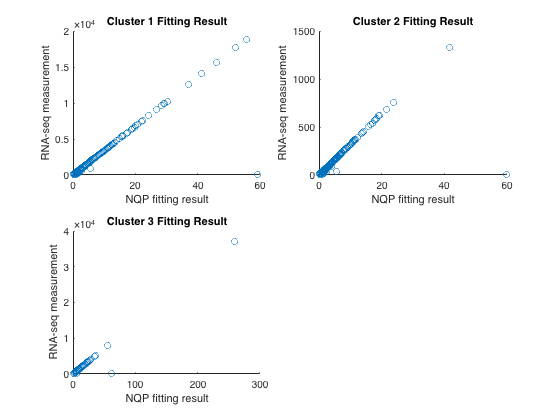


% Appearantly, data set #1 (exponential) and #7 (stationary) are very
% distinctive from all others. We can of course have dataset #6 a separate
% cluster as well, but 3 clusters will be faster for this demo so I'll do 3
% 
% To quantify the cluster of 6 experiments, we can either pick a
% representative set or take the centroid. In this demo I'll just pick
% dataset #4 as representative.

% And now let's do non-convex QP by calling the QP function with 
% "keffEstimate" set to true

clus = [1,4,7]; % three representatives chosen are dataset 1, 4, and 7

if ~exist('QPsol','var')
    [QPsol,model_qp] = overlayMultiomicsData(model_pc,data(:,clus),0,...
        waiver,'keffEstimate',true);
    rIdx = find(startsWith(model_qp.varnames,'R_'));
    rValues = QPsol.x(rIdx);
end

% Computation will likely take some time depending on your device. 
% 
% Plot non-convex QP results for manual inspection. It is looking okay in 
% general: nothing is too far outlying other than the dummy protein

varlen = length(model_pc.rxns) + length(find(startsWith(model_pc.rxns,'enzymeForm_')));
idx = [proteinExIdx, proteinExIdx+varlen, proteinExIdx+2*varlen];

figure;
for i = 1:3
    subplot(2,2,i);
    scatter(-QPsol.x(idx(:,i)),data(:,clus(i)));
    title(['Cluster ',num2str(i),' Fitting Result']);
    xlabel('NQP fitting result');
    ylabel('RNA-seq measurement');
end

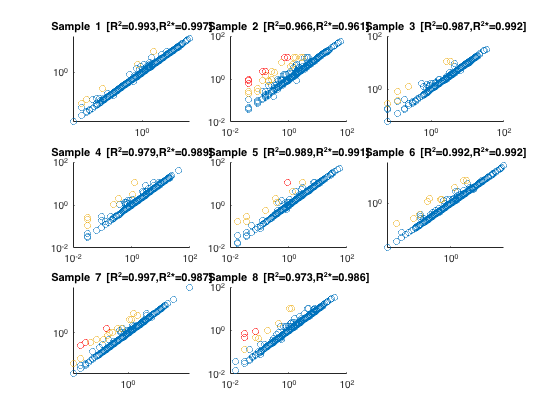


% Note that the only thing we want from non-convex QP is r values. 
% Now let's update the rate constants based on r values given by NQP

model_pc_new = updatePCModelKeffByR(model_pc,rValues);

clear clus i idx varlen;

% _7. Convex QP for context-specific modelling

% If you skipped non-convex QP, please run in command window:
% >> model_pc_new = model_pc;

% The target of convex QP is to find a protein vector in PC-model that is
% the most consistent with the data set. Convex QP is run separately for
% each set of data.

% Change solver param

changeCobraSolverParams('QP','feasTol',1e-9);
changeCobraSolverParams('QP','printLevel',0);

record_QPsol = []; % preallocate a recorder for solutions
data_fit = []; % record what exactly is fitted against

% Run convex QP in a loop

for i = 1:length(expNames)

    d = data(:,i);

    wt = d;
    wt(find(wt == 0)) = 1; % replacing all 0 to avoid div0
    wt = (1./wt);
    wt = wt / mean(wt);

    [QPsol_cv,model_qp] = overlayMultiomicsData(model_pc,d,0,waiver,'objWeight',wt);
%     [QPsol_cv,model_qp] = overlayMultiomicsData(model_pc,d,0,waiver);

    record_QPsol(:,i) = QPsol_cv.full;
    data_fit(:,i) = model_qp.c(proteinExIdx)./wt;

end

% Note that there is a weighting factor wt = 1/data. If we apply convex QP
% unweighted, the algorithm tends to allow all discrepancies to happen at
% low abundances, which often results in a worse fit in terms of R2. 
% This happens due to the fact that QP (minimizing the sum of squared 
% errors) works differently from minimizing R2, in which case the latter is
% our real target but we are executing the former by the solver. Applying a
% weighting factor that's inversely proportional to the abundance mitigates
% this problem. The solver will try to spread out residual more evenly
% throughout proteins of different abundances rather than concentrating
% residuals in the lowly expressed region. 
% 
% This part is very challenging to explain using only language, so please 
% comment out line 421 and uncomment line 422 to observe the output of 
% unweighted convex QP. In this case, unweighted results in a clearly worse
% fitting than the weighted. There are also cases where unweighted is not
% so much worse. You are free to play around the weighting function to find 
% the best fit possible, although the reciprocal of abundance is usually a 
% good starting point. 

% Visuallization

figure;

for i = 1:8

    subplot(3,3,i);
    ol = find((-record_QPsol(proteinExIdx,i)./data_fit(:,i) > 3) ...
        + (-record_QPsol(proteinExIdx,i)./data_fit(:,i) < 1/3));
    ol2 = find((-record_QPsol(proteinExIdx,i)./data_fit(:,i) > 10) ...
        + (-record_QPsol(proteinExIdx,i)./data_fit(:,i) < 0.1));
    scatter(data_fit(:,i),-record_QPsol(proteinExIdx,i));
    hold on;
%   plot outliers
    scatter(data_fit(ol,i),-record_QPsol(proteinExIdx(ol),i),[],[0.9290 0.6940 0.1250]);
    scatter(data_fit(ol2,i),-record_QPsol(proteinExIdx(ol2),i),[],'red');
    hold off;

%   calculate r2 and r2* (excluding dummy protein 1006)
    ed = [1:1005,1007:1510];
    [~,~,~,~,stat] = regress(data_fit(ed,i),-record_QPsol(proteinExIdx(ed),i));
    r2 = stat(1);

    X = log(data_fit(ed,i));
    Y = log(-record_QPsol(proteinExIdx(ed),i));
    idx = find(~isinf(X).*~isinf(Y));
    [~,~,~,~,stat] = regress(X(idx),Y(idx));
    r2_log = stat(1);

    title(['Sample ',num2str(i),' [R^2=',num2str(round(r2,3)),...
        ',R^2*=',num2str(round(r2_log,3)),']']);

    set(gca,'YScale','log');
    set(gca,'XScale','log');
end


% As we can see, the convex QP fitting result is in fact quite satisfying.
% This means for each set of data, we have found a protein vector that is
% highly similar and also gives a feasible metabolism. We can therefore
% proceed to the next step in OVERLAY.

% For the sake of simplicity in later steps, let's implement
% context-specific protein levels and put all models into a cell array

models = implementProteinConstraints(model_pc,record_QPsol,waiver,0.02);

clear i idx ed d ol ol2 QPsol_cv r2 r2_log stat wt X Y;

% _8. Debottlenecking

% There is a practical reason as for why this debottlenecking step exists
% and happens before PC-FVA. Please check the journal paper for explanation

models_db = cell(8,1);
FBAsols = cell(8,1);
relaxList = zeros(length(fullProtein),8);
test = zeros(8,1);

for i = 1:8
    model_alt = models{i};
    [FBAsols{i},models_db{i},relaxProt,relaxLevel] = proteinDebottleneck(model_alt,35);

    for j = 1:length(relaxProt)
        relaxList(find(strcmp(fullProtein,relaxProt{j})),i) = relaxLevel(j);
    end
    disp(FBAsols{i}.f);
    test(i) = FBAsols{i}.f;
end

    0.0311

    0.0155

    0.0286

    0.0217

    0.0225

    0.0292

    0.0254

    0.0192



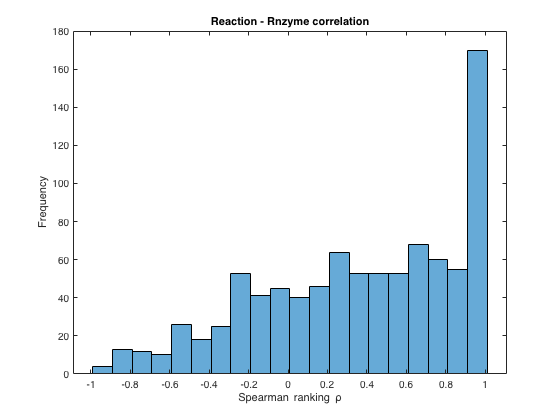


clear i j;

% The debottleneck budget (epsilon) needs to be chosen manually. In our 
% practice, we usually try a string of multiple values and locate an elbow.
% In this case we chose 35, but you might also choose 40 or some other
% values for epsilon as long as it appears appropriate. 
% 
%       epsilon         mean(FBAsols.f)         delta
%             0                       0           NaN
%             5                 4.30e-3        4.3e-3
%            10                 8.50e-3        4.2e-3
%            15                 1.28e-2        4.3e-3
%            20                 1.63e-2        3.5e-3
%            25                 1.97e-2        3.4e-3
%            30                 2.28e-2        3.1e-3
%            35*                2.58e-2        3.0e-3
%            40                 2.84e-2        2.6e-3
%            45                 3.05e-2        2.1e-3
%            50                 3.23e-2        1.8e-3

% The growth appears to make some basic sense (inspecting FBAsols{i}.f): 
%   - Exp 1 (exponential phase) has the highest growth potential among all
%     8 experiments.
%   - Exp 2 (anaerobic) is the least growth capable.�
% A not-so-good phenomenon:
%   - Exp 7 (stationary) is more growth capable than exp 8 (transition),
%   the latter is the second least growth capable. 

% It is very important to understand that the growth rates from PC-FBA
% represents only its capability in terms of mass balance and proteome. It
% can possibly grow slower (or much slower) than this value if it wants to.
% In fact, due to the under-determining nature of this system, it is
% impossible to compute the 'true' metabolism state with only expression
% data. 
% 
% However, we can dive deep into its capability and bottlenecks using FVA, 
% and this is what we are going to do. 

% _9. PC-FVA

% Let's think about each model - it is now tightly constrained (although
% still has some variability), or in an optimization terms, a polyhedral in
% a high dimensional space. The shape of this polyhedral is highly
% informative, yet it is also difficult to retrieve the info.
% 
% A natural approach is sampling the solution envelope and thus to 
% visualize the polyhedral set. Sampling is the ideal scenario: it allows 
% us to visualize the correlation between 2 or 3 variables simply by 
% flattening it in the directions of variables of interests. The 
% probability density function will also be very interesting to look at. 
% 
% However, the dimension of PC-models is usually too high (> 1e4) for the
% sampling algorithm to converge within a reasonable time frame. As an 
% inferior replacement of sampling, we decided to use FVA. FVA can not tell
% us the relationship between 3 or more variables, or provide a probability
% density function. But it at least can provide us with the relationship
% between two variables, of which one of them is the objective (biomass).
% 
% This is achieved by maximizing/minimizing each flux while constraining 
% the objective function to a percentage of its optimum (a.k.a. optimum
% percentage) as well as abiding to the protein constraints. All results 
% will be stored in FVAsols.

if ~exist('FVAsols','var')
    FVAsols = contextSpecificPCFVA(models_db,model_ori.rxns,[0,0.5,0.9,0.99]);
end

% FVA will take from 30 min to a few hours to complete. 

% Apart from the variability of fluxes, we also want to know the level of
% enzymes that can catalyze these fluxes. This can be easily done by doing
% another FVA on reactions enzymes exclusively. Note that only enzymatic
% reactions have a set of enzymatic reactions. In the journal paper, this
% is demonstrated as the 'expression level related to a certain rxn'.

if ~exist('FVAsols_enz','var')

    FVAsols_enz = zeros(length(model_ori.rxns),8);
    
    for i = 1:length(model_ori.rxns)
    
        if isempty(model_ori.rules{i}) % pass on spontaneous rxns
            continue;
        end
    
        idx = find(strcmp(model_pc.rxns,['EX_enzyme_',model_ori.rxns{i}]));
        
        for j = 1:8
            model_alt = changeObjective(models_db{j},model_pc.rxns{idx});
            FBAsol_alt = optimizeCbModel(model_alt,'max');
            FVAsols_enz(i,j) = FBAsol_alt.f;
        end
    end
end

% This enzyme FVA will take much less time to complete.

% _10. PC-FVA unveils metabolic insights

% There are a lot of information in this FVA result, and there might be
% multiple methods to interrogate the result according to your objective. 
% We have developed a systematic way to study the relationship between the
% reaction of interest (biomass in this case) with all other reactions as
% well as expressions. This is significant because we can therefore suggest
% 'lever' genes of which varying expression is likely impacting the target
% reaction disproportionately. 

% The first step is to find all 'expression-dependent' reactions. This is
% done by comparing the maximum fluxes versus enzyme levels for each rxn.
% We are using the Spearman ranking (rho) to examine the correlation
% between max fluxes and expression. 

maxFlux = max(abs(FVAsols),[],3); % find max flux for each rxn + exp pair
rhos_RE = diag(corr(maxFlux',FVAsols_enz','Type','Spearman'));

figure;
histogram(rhos_RE,20);
title('Reaction - Rnzyme correlation');
ylabel('Frequency');
xlabel('Spearman ranking \rho');

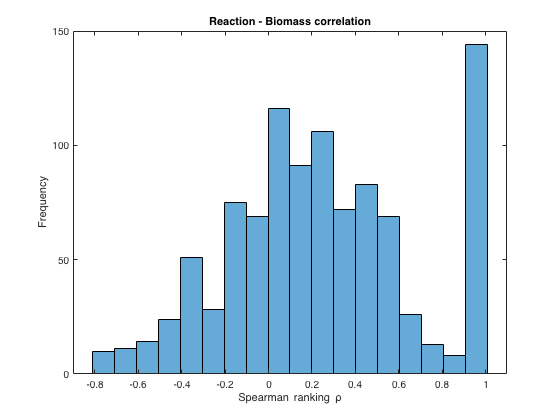


% The histogram of rho should be significantly skewed: there are a lot more
% strong positive correlations than negative once. In fact, there is no
% systematic reason for these negative rhos, so they are purely
% coincidental; on the other hand, strong positive correlation suggests a
% expression-dependent reaction. In this case, rho >= 0.73 is statistically
% significant (p <= 0.05), and clearly, having more sets of data provides 
% better accuracy in expression-dependent reaction recognition. 
% 
% Note that there are 2023 metabolic reactions, of which 1558 are enzymatic
% reaction, yet we only get 910 valid rho. This means 648 enzymatic
% reactions are incapable to carry any flux in all of 8 models, due to 
% either mass balance or enzymatic constraints. 
% 
% These expression-dependent reactions (there are 274 of them) are levers
% to manipulate the solution space, as changing them will likely lead to
% the change of their respective fluxes. But we still need to learn which
% levers are acting on the reaction of interests. This can again be done by
% correlation analysis.

rhos_RR = corr(maxFlux','Type','Spearman');
rhos_RR = rhos_RR([1:2014,2016:2023],2015);

figure;
histogram(rhos_RR,18);
title('Reaction - Biomass correlation');
ylabel('Frequency');
xlabel('Spearman ranking \rho');

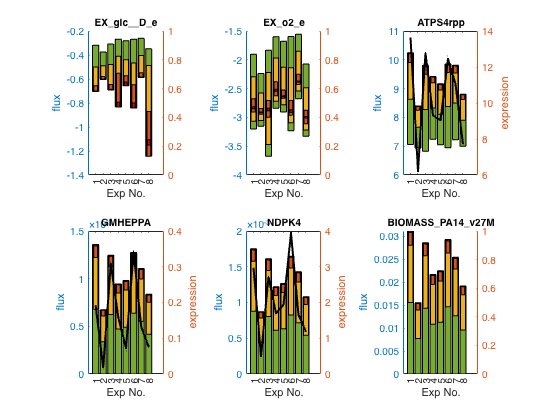


% There are 142 reactions that are highly correlated (rho >= 0.9) with the 
% biomass. Out of these 142 reactions, 8 of them are also expression
% dependent (rho_RE > 0.73). They are the lever reactions we are finding.
% Let's visualize some of them next (ATPS4rpp, GMHEPPA, and NDPK4)

% The most simple way to visualize it is to plot all numbers of one 
% reaction on the same graph (FVAsols(ii,:,:)). This plotting method is the
% most appropriate when we have time-course expression data, so we are also
% observing metabolism shifts over time. If the reaction is enzymatic, we 
% should also plot its enzymatic level. 

rxnList = {'EX_glc__D_e','EX_o2_e','ATPS4rpp','GMHEPPA','NDPK4','BIOMASS_PA14_v27M'};
clr = {[0.4660 0.6740 0.1880],...
    [0.9290 0.6940 0.1250],...
    [0.8500 0.3250 0.0980],...
    [1 0 0]};

plotPCFVASolutions(FVAsols,model_ori,rxnList,[2,3],FVAsols_enz,clr);


% From the plotting, we can clearly see the correlation of flux-flux and
% flux-expression. Glucose and oxygen uptake are vital for P. aeruginosa in
% any experiment, but their flux do not appear to be the growth-determining
% factor. 

% This last section may seem complicated, but it is nothing more than an
% attempt to glean the information from the context-specific PC-model.
% It is up to the user how he/she wants to interpret what OVERLAY offers.
% But if you are getting confused or having little idea, what we have done 
% in the journal article might be a good starting point for you, which is
% demonstrated here in fine details. 

clear i j idx model_alt FBAsol_alt;

% _11. Epilogue

% This is a complete showcase of what OVERLAY has to offer to the user
% based on its design. As you may appreciate, the workflow is very
% streamlined and can be used quite easily on a dataset of interests to
% harvest valuable insights that won't be available otherwise. We as
% authors composed this tutorial and have high expectations for OVERLAY
% workflow, believing it has enough versatility to address problems in
% biotechnology, microbiology, and medicine. It is also capable of working
% with the wet lab - OVERLAY can interpret measurements from the lab and
% therefore suggest the next step, a trait that we want to explicitly
% emphasize to promote in-silico modelling to wet lab scientists. 
% 
% Of course, the analysis does not stop here. It is up to the user if
% you wants to adopt this way of explanation or taking another route. In
% fact, we are still developing new functions, especially regarding new
% unbiased polyhedral set exploration tool (currently using FVA) and
% integrating thermodynamic data to OVERLAY. We are whole-heartedly
% welcoming to anyone who wants to share their opinions and inspirations on
% this toolbox. 

%% Acknowledgments
% 
% This work is supervised by Laurence Yang and developed with the help from
% Sanjeev Dahal. The author thanks Ziying Wang for her assistance in 
% testing.
% 
%% Reference
% 
% _1. Yao, H., Dahal, S. & Yang, L. Novel context-specific genome-scale 
% modelling explores the potential of triacylglycerol production by 
% Chlamydomonas reinhardtii. Microb Cell Fact 22, 13 (2023).
% 
% _2. Yao, Haoyang, and Laurence Yang. "PROSO Toolbox: a unified protein-
% constrained genome-scale modelling framework for strain designing and 
% optimization." arXiv preprint arXiv:2308.14869 (2023).
% 
% _3. Yurkovich, James T., Laurence Yang, and Bernhard O. Palsson. 
% "Systems-level physiology of the human red blood cell is computed from 
% metabolic and macromolecular mechanisms." bioRxiv (2019): 797258.
% 

